# **Proyecto Control Grupo 3-3**

Integrantes:

Brandon Jiménez Campos C33972

Rodrigo Sánchez Araya C37259

Fabricio Araya Cháves C39539

# **Obtener los datos del archivo .csv**

data = readmatrix("../Data/150_120_CQRobot.csv");
load("salida_sn.mat")
t = data(:,1); %tiempo
u = data(:,2); %señal de entrada
y = data(:,3); %señal de salida

Ts = 0.0370;

# **Gráfica de la salida del sistema**

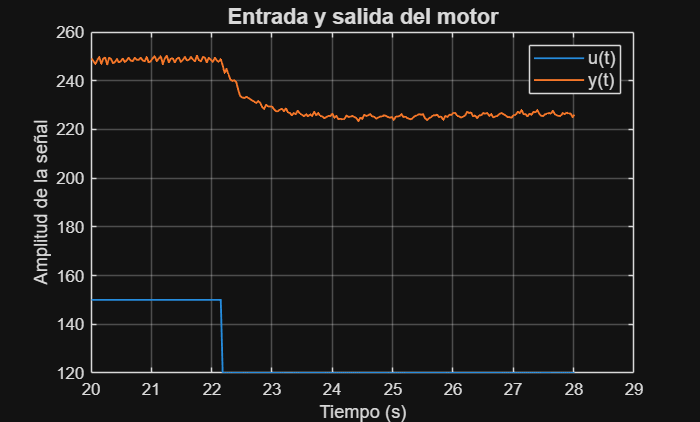

figure(1);
plot(t,u,t,y,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('u(t)', 'y(t)','FontSize',11);
title('Entrada y salida del motor', 'FontSize',13);
grid on;

# **Eliminar el DC Offset**

porcentaje_inicial = 0.10; % Se toma un aproximado de qué porcentaje de la respuesta 
num_puntos = length(y);
puntos_iniciales = round(porcentaje_inicial * num_puntos);
dc_offset_u = mean(u(1:puntos_iniciales));
dc_offset_y = mean(y(1:puntos_iniciales));

u_sindc = u - dc_offset_u;
y_sindc = y - dc_offset_y;

# **Gráfica de la salida sin el DC Offset**

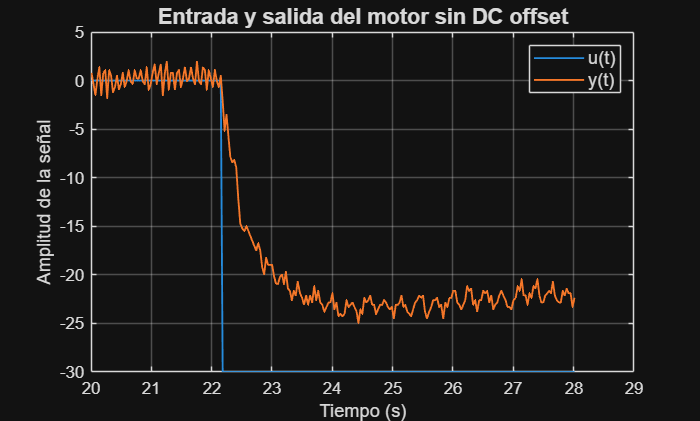

figure(2);
plot(t, u_sindc, t, y_sindc, 'LineWidth',1.1);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# **Abrir el System Identification Toolbox**

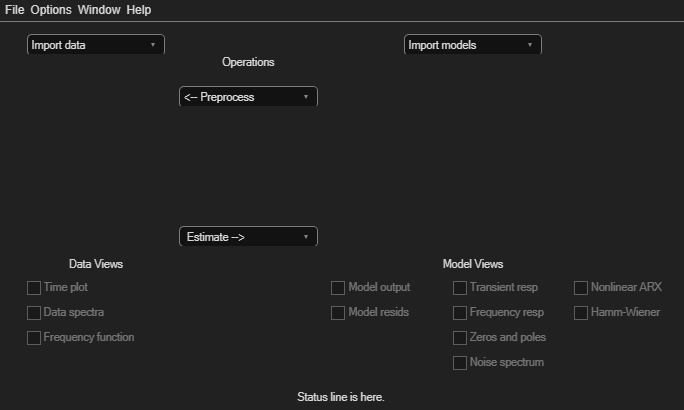

systemIdentification();

Se puede cargar el valor de la planta ya calculada con un 90.84% de precisión dándole click al modelo_primer_orden.mat

# Gráfica con del modelo de Toolbox

t1 = (20:0.0370:29)'

t1 =            20
       20.037
       20.074
       20.111
       20.148
       20.185
       20.222
       20.259
       20.296
       20.333
        20.37
       20.407
       20.444
       20.481
       20.518


%Planta obtenida por toolbox
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.


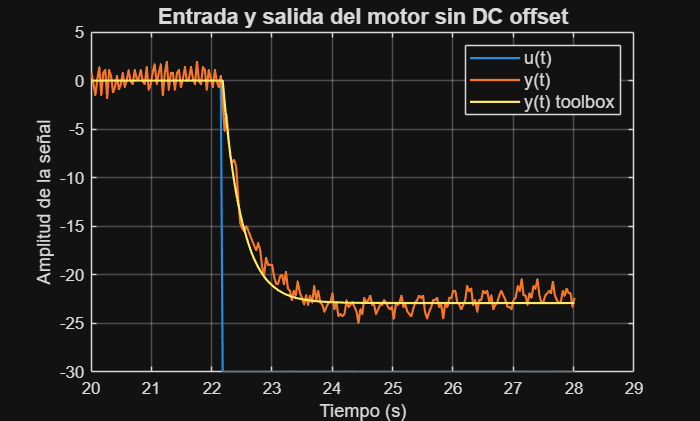

Kp = 0.7634;
T = 0.3649;
P = Kp/(T*s+1);

y_sim = lsim(P, u_sindc, t1);

figure(3);
plot(t, u_sindc, t, y_sindc, t, y_sim, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) toolbox', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Método de mínimos cuadrados

Y = y_sindc(3:end);
X = [y_sindc(2:end-1) y_sindc(1:end-2) u_sindc(2:end-1) u_sindc(1:end-2)];

cita = (X' * X) \ (X' * Y);

cita = round(cita,4); % se redondea el cita a 4 decimales
z = tf('z');
Hz = tf([cita(3) cita(4)], [1 -cita(1) -cita(2)], Ts); % se crea la función de transferencia
format shortG
Hz


Hz =
 
     0.1437 z - 0.0514
  -----------------------
  z^2 - 0.5008 z - 0.3763
 
Sample time: 0.037 seconds
Discrete-time transfer function.


# Gráfica con el método de mínimos cuadrados

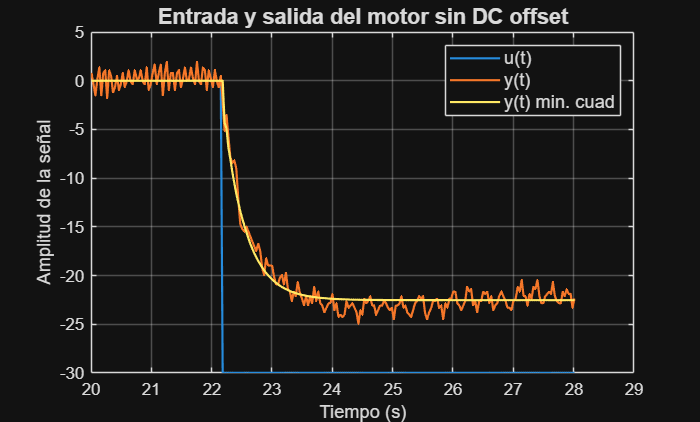

y_sim1 = lsim (Hz, u_sindc);

figure(4);
plot(t, u_sindc, t, y_sindc, t, y_sim1, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) min. cuad', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# ** Datos necesarios para el método de Alfaro**

porcentaje_final = 0.10; % Se toma un aproximado de donde la respuesta tiene su valor final
num_puntos = length(y);
puntos_final = round(porcentaje_final * num_puntos);
y_final = y_sindc(end-puntos_final+1:end);
promedio_yfinal = mean(y_final);

% Calcular y_inicial 
puntos_iniciales = round(0.10 * num_puntos);
y_inicial = mean(y_sindc(1:puntos_iniciales));

% Encontrar cambio_esc
cambio_esc = find(u_sindc < 0, 1);

deltau = u(1) - u(cambio_esc);

deltay = y_inicial - promedio_yfinal;

deltay25 = y_inicial - 0.25 * deltay;
deltay50 = y_inicial - 0.5 * deltay;
deltay75 = y_inicial - 0.75 * deltay;

% Se encuentran las posiciones en el vector tiempo de cada porcentaje de delta y
% Para t25
todos_t25 = find(y_sindc(cambio_esc:end) <= deltay25);
pos_t25 = todos_t25(min(1, end)) + cambio_esc - 1;

% Para t50
todos_t50 = find(y_sindc(cambio_esc:end) <= deltay50);
pos_t50 = todos_t50(min(1, end)) + cambio_esc - 1;

% Para t75
todos_t75 = find(y_sindc(cambio_esc:end) <= deltay75);
pos_t75 = todos_t75(min(1, end)) + cambio_esc - 1;

% Se obtiene los tiempos en donde ocurren los porcentajes y el cambio escalon
t25_tot = t(pos_t25);
t50_tot = t(pos_t50);
t75_tot = t(pos_t75);
tcambio = t(cambio_esc);

% Se resta el tiempo antes de hacer el cambio escalón
t25 = t25_tot - tcambio;
t50 = t50_tot - tcambio;
t75 = t75_tot - tcambio;

# Método de PDMTM Alfaro (método de 2 puntos)

a = 0.5776

a =        0.5776


b = 1.5552

b =        1.5552


K = deltay / deltau;
Talf = a*(t75 - t25);
%No se calcula L ya que la planta no tiene tiempo muerto

# Gráfica con el método de Alfaro PDMTM

s = tf('s');
P1 = K / (Talf*s + 1)^2


P1 =
 
            0.7339
  --------------------------
  0.06116 s^2 + 0.4946 s + 1
 
Continuous-time transfer function.


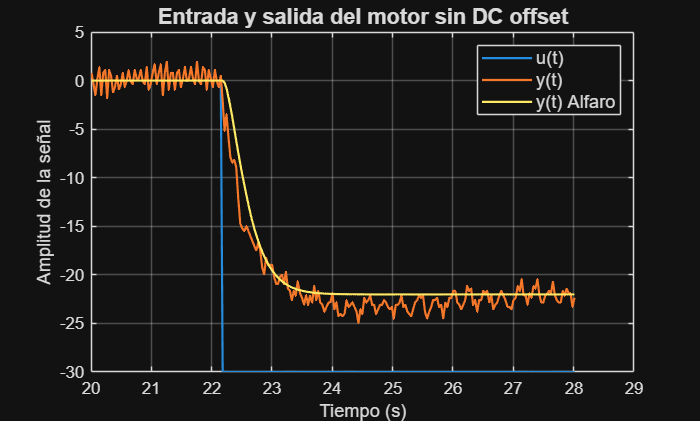

y_sim2 = lsim (P1, u_sindc, t1);
figure(5);

plot(t, u_sindc, t, y_sindc, t, y_sim2, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)', 'y(t) Alfaro','FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Cálculo de lo necesario para Ho

deltay35 = y_inicial - 0.35 * deltay;
deltay85 = y_inicial - 0.85 * deltay;

% Se encuentran las posiciones en el vector tiempo de cada porcentaje de delta y
% Para t35
todos_t35 = find(y_sindc(cambio_esc:end) <= deltay35);
pos_t35 = todos_t35(min(1, end)) + cambio_esc - 1;

% Para t85
todos_t85 = find(y_sindc(cambio_esc:end) <= deltay85);
pos_t85 = todos_t85(min(1, end)) + cambio_esc - 1;

% Se obtiene los tiempos en donde ocurren los porcentajes y el cambio escalon
t35_tot = t(pos_t35);
t85_tot = t(pos_t85);

% Se resta el tiempo antes de hacer el cambio escalón
t35 = t35_tot - tcambio;
t85 = t85_tot - tcambio;

# Método de PDMTM Ho (método de 2 puntos)

aho = 0.463

aho =         0.463


K = deltay / deltau;
Tho = aho*(t85 - t35);

%No se calcula L ya que la planta no tiene tiempo muerto
P2 = K / (Tho*s + 1)^2


P2 =
 
            0.7339
  --------------------------
  0.05966 s^2 + 0.4885 s + 1
 
Continuous-time transfer function.


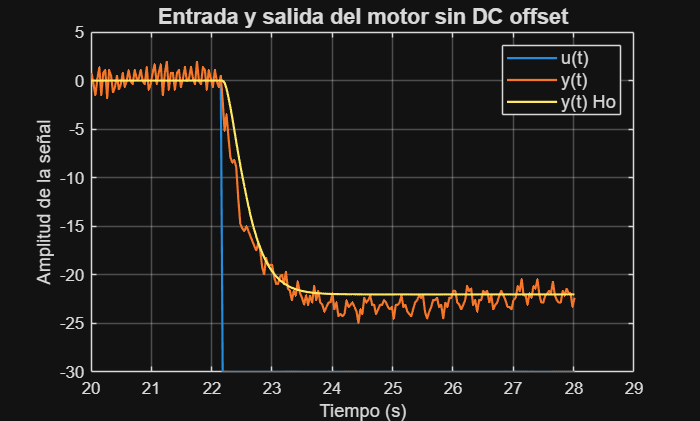

y_sim3 = lsim (P2, u_sindc, t1);

figure(6);
plot(t, u_sindc, t, y_sindc, t, y_sim3, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) Ho', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Método de alfaro 3 puntos

a3 = (-0.6240*t25 + 0.9866*t50 - 0.3626*t75)/(0.3533*t25 - 0.7036*t50 + 0.3503*t75);
T3 = (t75 - t25) / (0.9866+0.7036*a)

T3 =       0.30736


% No se calcula L ya que no tiene tiempo muerto

P3 = K/((T3*s+1)*(a*T3*s+1))


P3 =
 
            0.7339
  --------------------------
  0.05457 s^2 + 0.4849 s + 1
 
Continuous-time transfer function.


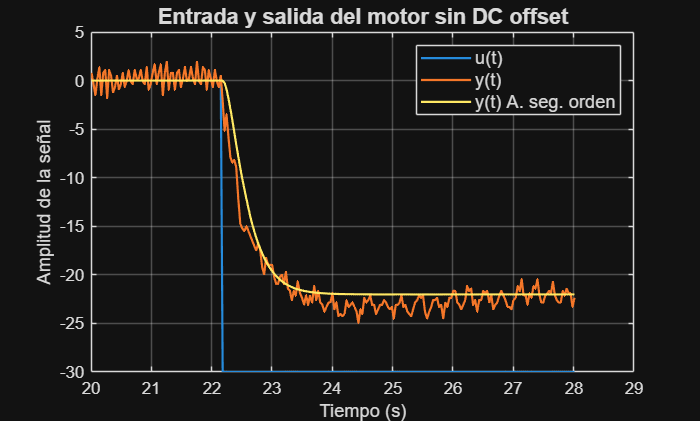

y_sim4 = lsim (P3, u_sindc, t1);

figure(7);
plot(t, u_sindc, t, y_sindc, t, y_sim4, 'LineWidth',1.3);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) A. seg. orden', 'FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Comparación de las gráficas

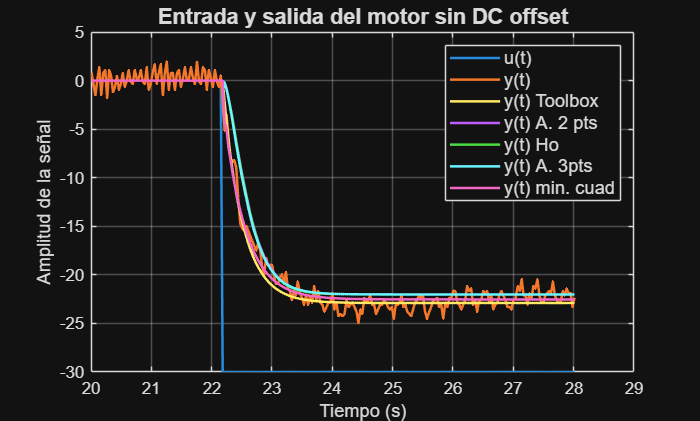

figure(8);
plot(t, u_sindc, t, y_sindc, t, y_sim, t, y_sim2, t, y_sim3, t, y_sim4,t, y_sim1,'LineWidth',1.5);
xlabel('Tiempo (s)', 'FontSize',11);
ylabel ('Amplitud de la señal', 'FontSize',11);
legend ('u(t)', 'y(t)','y(t) Toolbox','y(t) A. 2 pts', 'y(t) Ho', 'y(t) A. 3pts', 'y(t) min. cuad','FontSize',11);
title ('Entrada y salida del motor sin DC offset', 'FontSize',13);
grid on;

# Cálculos para elección de modelo de planta

%% Planta obtenida a través de toolbox
e_tbx = y_sindc - y_sim; % error de la planta de toolbox

IAE_tbx = sum(abs(e_tbx)) * Ts; % índice integral de error absoluto de la planta toolbox
ISE_tbx = sum(e_tbx.^2) * Ts; % índice de error cuadrático de la planta toolbox
ajuste_tbx = 100 * (1 - norm(e_tbx)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta toolbox

%% Planta obtenida a través de Alfaro 2 puntos
e_alfdos = y_sindc - y_sim2; % error de la planta de Alfaro 2 puntos

IAE_alfdos = sum(abs(e_alfdos)) * Ts; % índice integral de error absoluto de la planta de Alfaro 2 puntos
ISE_alfdos = sum(e_alfdos.^2) * Ts; % índice de error cuadrático de la planta Alfaro 2 puntos
ajuste_alfdos = 100 * (1 - norm(e_alfdos)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta de Alfaro 2 puntos


%% Planta obtenida a través de Ho 2 puntos
e_hodos = y_sindc - y_sim3; % error de la planta de Ho 2 puntos

IAE_hodos = sum(abs(e_hodos)) * Ts; % índice integral de error absoluto de la planta de Ho 2 puntos
ISE_hodos = sum(e_hodos.^2) * Ts; % índice de error cuadrático de la planta Ho 2 puntos
ajuste_hodos = 100 * (1 - norm(e_hodos)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta de Ho 2 puntos

%% Planta obtenida a través de Alfaro 3 puntos
e_alftres = y_sindc - y_sim4; % error de la planta de Alfaro 3 puntos

IAE_alftres = sum(abs(e_alftres)) * Ts; % índice integral de error absoluto de la planta de Alfaro 3 puntos
ISE_alftres = sum(e_alftres.^2) * Ts; % índice de error cuadrático de la planta Alfaro 3 puntos
ajuste_alftres = 100 * (1 - norm(e_alftres)/norm(y_sindc-mean(y_sindc))); % porcentaje de ajuste de planta de Alfaro 3 puntos

# Datos relevantes y elección de planta

IAE_vec = [IAE_tbx, IAE_alfdos, IAE_hodos, IAE_alftres];
ISE_vec = [ISE_tbx, ISE_alfdos, ISE_hodos, ISE_alftres];
ajuste_vec = [ajuste_tbx, ajuste_alfdos, ajuste_hodos, ajuste_alftres];
nombres = {'Toolbox', 'Alfaro 2p', 'Ho 2p', 'Alfaro 3p'};

[~, mejor_IAE] = min(IAE_vec);
[~, mejor_ISE] = min(ISE_vec);
[~, mejor_ajuste] = max(ajuste_vec);

%% Resultados
fprintf('Mejor IAE: %s (%.4f)\n', nombres{mejor_IAE}, IAE_vec(mejor_IAE));

Mejor IAE: Toolbox (7.2772)


fprintf('Mejor ISE: %s (%.4f)\n', nombres{mejor_ISE}, ISE_vec(mejor_ISE));

Mejor ISE: Toolbox (9.1954)


fprintf('Mejor Ajuste: %s (%.4f%%)\n', nombres{mejor_ajuste}, ajuste_vec(mejor_ajuste));

Mejor Ajuste: Toolbox (90.0214%)


# Cálculo controlador PI con Síntesis Analítica para P1D

%Cálculo tauc de acuerdo Ms = 1.0
tauc = 3.8 * T;
%Cálculo parámetros del controlador
ksn = (2- tauc)/(tauc * Kp);
tisn = tauc * T * (2 - tauc);

%Controlador C2 con método síntesis analítica
C1 = ksn *(1 + 1/(tisn*s))


C1 =
 
  0.1798 s + 0.5795
  -----------------
      0.3104 s
 
Continuous-time transfer function.


# Gráfica salida con controlador por Síntesis analítica

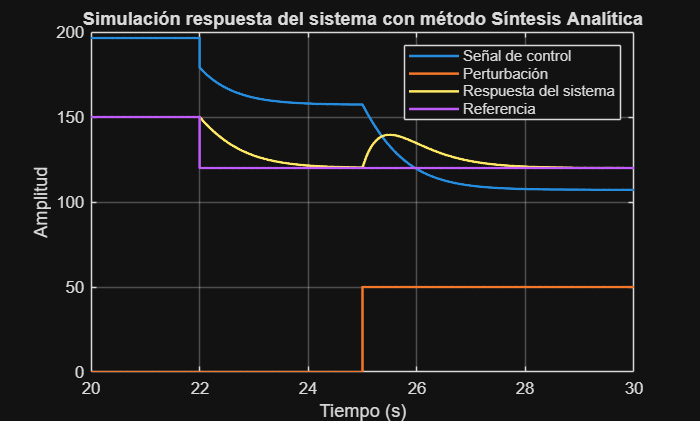

Myr1 = ( C1 * P ) /(1+ C1 * P ) ;
Myd1 = minreal ( P /(1+ C1 * P ) ) ;

r = u_sindc;

d = 0; %perturbacion
d ( t1 >= 25) = 50;
yr1 = lsim ( Myr1 , r, t1 ) ;
yd1 = lsim ( Myd1 , d , t1 ) ;
y1 = yr1 + yd1;

figure (9);
plot(out_sn.tout, out_sn.ctrlsn.signals.values, 'LineWidth',1.5)
hold on
plot(out_sn.tout, out_sn.salidasn.signals.values(:,1), 'LineWidth',1.5)
plot(out_sn.tout, out_sn.salidasn.signals.values(:,2), 'LineWidth',1.5)
plot(out_sn.tout, out_sn.salidasn.signals.values(:,3), 'LineWidth',1.5)
hold off
xlabel('Tiempo (s)')
ylabel('Amplitud')
title("Simulación respuesta del sistema con método Síntesis Analítica")
legend('Señal de control', 'Perturbación','Respuesta del sistema','Referencia')
grid on

## Índices para resultador teóricos controlador Síntesis Analítica

% Error
indices_r = out_sn.tout <= 24.5; %indices de los valores de tiempo menores o iguales a 24.5 para servo
indices = out_sn.tout >= 24;   % Índices de los valores de tiempo mayores o iguales a 24
indices_te = out_sn.tout >= 25;
t_values = out_sn.tout;
r_values = out_sn.salidasn.signals.values(:,3);
y1_values = out_sn.salidasn.signals.values(:,2);
r_after_24 = r_values(indices);   % Valores de 'r' después de t=24
y1_after_24 = y1_values(indices); % Valores de 'y2' después de t=24
r_before_24 = r_values(indices_r);
y1_before_21 = y1_values(indices_r);
t_values = t_values(indices_te);
y_sn_te = y1_values(indices_te);

e_snT = r_after_24 - y1_after_24;
e_snT_1 = r - y1;
e_snT_r = r_before_24 - y1_before_21;

% Valor final de la referencia (estado estacionario)
y_final = r_values(end);

% Calcular los límites del 2% (±2%)
y98 = 0.98 * y_final; % 98% del valor final
y102 = 1.02 * y_final; % 102% del valor final

% Encontrar índices donde la respuesta está dentro de la banda del 2%
ind_98 = find((y_sn_te >= y98), 6, 'first');
ind_98 = ind_98(5); % Tomar el quinto valor, ya que al inicio toma valores cercanos a la ref pero es antes del salto

% Encontrar índices donde la respuesta está dentro de la banda del 2%
ind_102 = find((y_sn_te <= y102), 6, 'first');
ind_102 = ind_102(5); % Tomar el quinto valor, ya que al inicio toma valores cercanos a la ref pero es antes del salto

% Tomar el máximo de ambos índices
ind_te2 = max(ind_98, ind_102);

% Calcular te2 restando el punto de perturbación
te2_snT = t_values(ind_te2) - 25;


% Cálculo de índices de desempeño
IAEd_snT = sum(abs(e_snT_1)) * Ts;
IAEr_snT = sum(abs(e_snT_r)) * Ts;
ISEd_snT = sum(e_snT_1.^2) * Ts;
Emaxsn = max(abs(e_snT)); % Error máximo
TVud_sn = sum(abs(diff(out_sn.ctrlsn.signals.values))); % esfuerzo de control

IAEd_snT

IAEd_snT =        48.284


IAEr_snT

IAEr_snT =         78.23


ISEd_snT

ISEd_snT =        712.05


Emaxsn

Emaxsn =        19.579


TVud_sn

TVud_sn =        89.286


te2_snT

te2_snT =          2.35


# Gráfica prueba experimental del controlador por Síntesis Analítica

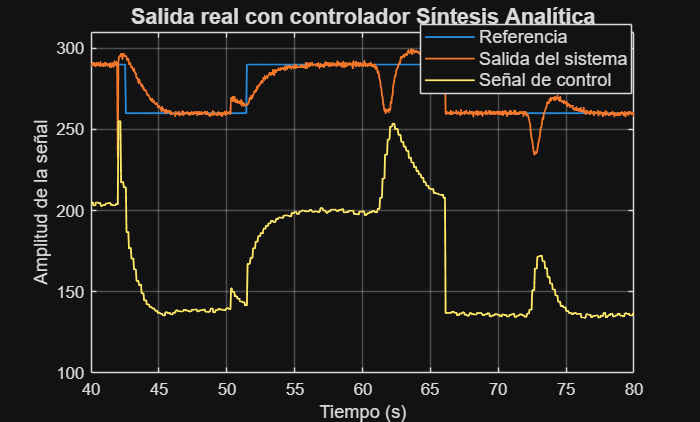

datasn = readmatrix("../Data/datos_sintesis_analitica.csv");
tsn = datasn(:,1); %tiempo
rsn = datasn(:,2); %señal de referencia
usn = datasn(:,3); %señal de control
ysn = datasn(:,4); %salida del sistema

figure(10);
plot(tsn,rsn,tsn,ysn,tsn,usn,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('Referencia','Salida del sistema','Señal de control','FontSize',11, "Position", [0.5997 0.7990 0.3036, 0.1262]);
title('Salida real con controlador Síntesis Analítica', 'FontSize',13);
ylim ([100 310])
xlim ([40 80])
grid on;

## Índices para prueba experimental con controlador por Síntesis Analítica

% Error

% Definir el intervalo de tiempo [t1, t2] para servocontrol
t_1 = 51.4371;  % Tiempo inicial
t_2 = 60.8337;  % Tiempo final

% Filtrar los índices de los datos dentro del intervalo de tiempo
idx = (tsn >= t_1) & (tsn <= t_2); 
Ts_sn = mean(diff(tsn(idx)));  % El tiempo de muestreo 
e_sn = rsn(idx) - ysn(idx);

% Definir el intervalo de tiempo [t10, t11] para control regulatorio
t_10 = 72.2;  % Tiempo inicial
t_11 = 80;  % Tiempo final

% Filtrar los índices de los datos dentro del intervalo de tiempo
idxd = (tsn >= t_10) & (tsn <= t_11); 
ed_sn = rsn(idxd) - ysn(idxd);

% Cálculo de índices de desempeño regulatorio
IAEd_sn = sum(abs(ed_sn)) * Ts_sn;
ISEd_sn = sum(ed_sn.^2) * Ts_sn;
emaxd_sn = max(abs(ed_sn));
TVud_sn  = sum(abs(diff(usn(idxd))));
% Cálculo de índices de desempeño servocontrol
IAEr_sn = sum(abs(e_sn)) * Ts_sn;
ISEr_sn = sum(e_sn.^2) * Ts_sn;

%Calculo error 2%
yfinalsn = 260; %Arreglar esto, poner el inicio y ya
bandasn = yfinalsn * 0.02;
ind_sn = find((abs(ed_sn) <= bandasn), 15, 'first');
ind_te2_sn = max(ind_sn);
te2_sn = ind_te2_sn * Ts_sn;

te2_sn

te2_sn =        3.2121



IAEd_sn

IAEd_sn =        35.831


ISEd_sn

ISEd_sn =        433.75


IAEr_sn

IAEr_sn =        34.885


emaxd_sn

emaxd_sn =         25.55


TVud_sn

TVud_sn =         97.04


ISEr_sn

ISEr_sn =        427.02


# Controlador con el método Lambda

lambda = 0.6*T; % se elige luego de un barrido de valores de lambda y este es el más idóneo
Kclbd = T/(Kp*lambda);
Tilbd = T;

C2 = Kclbd *(1 + 1/(Tilbd*s))


C2 =
 
  0.7967 s + 2.183
  ----------------
      0.3649 s
 
Continuous-time transfer function.


# Gráfica del controlador con el método Lambda

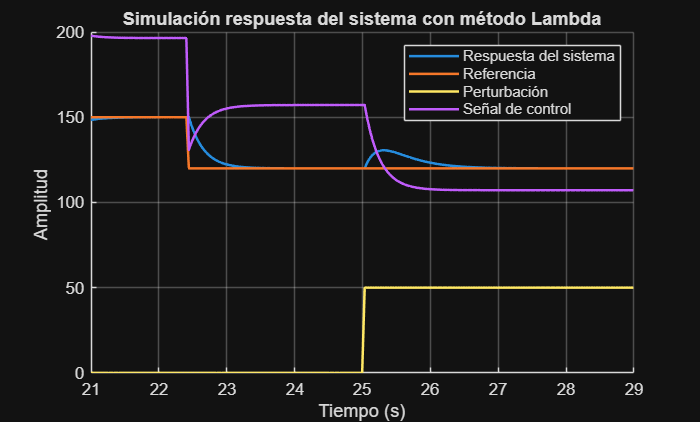

Myr1 = ( C2 * P ) /(1+ C2 * P ) ;
Myd1 = minreal ( P /(1+ C2 * P ) ) ;
Mur1 = C2/(1+C2*P);
Mud1 = (-C2*P)/(1+C2*P);

r = u_sindc;
r2 = u;

d = 0; %perturbacion
d( t1 >= 25) = 50;
d= d';
yr1 = lsim ( Myr1 , r , t1 ) ;
yd1 = lsim ( Myd1 , d , t1 ) ;
y1 = yr1 + yd1;
yr4 = lsim ( Myr1 , r2 , t1 ) ;
y4 = yr4 + yd1;

ur1 = lsim (Mur1, r2, t1);
ud1 = lsim(Mud1, d, t1);
u1 = ur1 + ud1;

figure (12);
title ('Simulación respuesta del sistema con método Lambda') ;
xlabel ('Tiempo (s)') ;
ylabel ('Amplitud ') ;
hold on ;
grid ('on') ;
plot (t1 , y4, t1, r2,t1,d,t1,u1, 'LineWidth', 1.5);
xlim ([21 29])
legend('Respuesta del sistema', 'Referencia', 'Perturbación','Señal de control');

## Índices para resultados teóricos Controlador Lambda

% Error
indices = t1 >= 24; % Índices de los valores de tiempo mayores o iguales a 24
indices_r = t1 <= 24.5; % índices para los valores de tiempo menores o iguales a 24.5 para servocontrol
indices_te = t1 >= 25;
t1_after = t1(indices);
r_after_24 = r(indices); % Valores de 'r' después de t=24
y1_after_24 = y1(indices); % Valores de 'y2' después de t=24
r_before_24 = r(indices_r);
y1_before_24 = y1(indices_r);
t1_te = t1(indices_te);
r_te = r(indices_te);
y4_te = y4(indices_te);
e_lmbdT = r_after_24 - y1_after_24; % calcular el error
e_lmbdT_r = r_before_24 - y1_before_24; %calcular el error en el tiempo de servocontrol

% Valor final de la referencia (estado estacionario)
y_final = r2(end);

% Calcular los límites del 2% (±2%)
y98 = 0.98 * y_final; % 98% del valor final
y102 = 1.02 * y_final; % 102% del valor final

% Encontrar índices donde la respuesta está dentro de la banda ±2%
ind_98 = find((y4_te >= y98), 2, 'first');
ind_98 = ind_98(2); % Tomar el segundo elemento

% Encontrar índices donde la respuesta está dentro de la banda ±2%
ind_102 = find((y4_te <= y102), 2, 'first');
ind_102 = ind_102(2); % Tomar el segundo elemento

% Tomar el máximo de ambos índices
ind_te2 = max(ind_98, ind_102);

% Calcular te2 restando el punto de perturbación
te2_lbdT = t1_te(ind_te2) - 25;

% Cálculo de índices de desempeño
IAEd_lbdT = sum(abs(e_lmbdT)) * Ts;
IAEr_lbdT = sum(abs(e_lmbdT_r)) * Ts;
ISEd_lbdT = sum(e_lmbdT.^2) * Ts;
Emaxlbd = max(abs(e_lmbdT)); % Error máximo
TVud_lbd = sum(abs(diff(u1))); % esfuerzo de control

IAEd_lbdT

IAEd_lbdT =        8.3496


IAEr_lbdT

IAEr_lbdT =        7.1383


ISEd_lbdT

ISEd_lbdT =        59.809


Emaxlbd

Emaxlbd =        10.627


TVud_lbd

TVud_lbd =        272.68


te2_lbdT

te2_lbdT =         1.142


# Gráfica prueba experimental con el controlador por el método Lambda

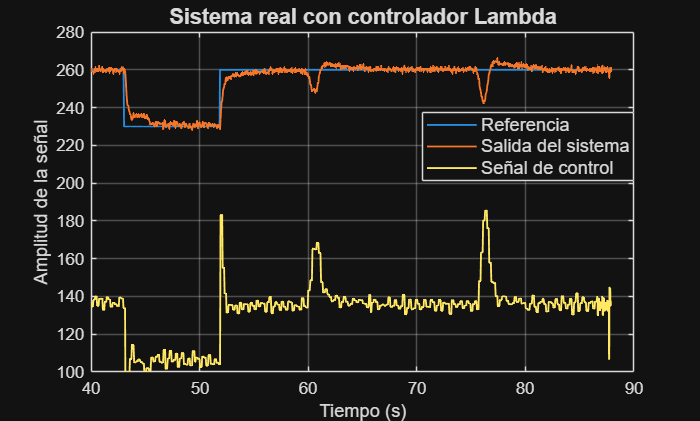

datalbd = readmatrix("../Data/datos_lambda.csv");
tlbd = datalbd(:,1); %tiempo
rlbd = datalbd(:,2); %señal de referencia
ulbd = datalbd(:,3); %señal de control
ylbd = datalbd(:,4);

figure(13);
plot(tlbd,rlbd,tlbd,ylbd,tlbd,ulbd,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('Referencia','Salida del sistema','Señal de control','FontSize',11,"Position", [0.6024 0.5889 0.3036, 0.1262]);
title('Sistema real con controlador Lambda', 'FontSize',13);
ylim ([100 280])
xlim ([40 90])
grid on;

## Indices para resultados experimentales Controlador Lambda

% Error Servocontrol
t3 = 40.2206;
t4 = 58.1935;
idx1 = (tlbd >= t3) & (tlbd <= t4);
Tslbd = mean(diff(tlbd(idx1)));  % El tiempo de muestreo 
e_lbd = rlbd(idx1) - ylbd(idx1);

% Error Regulatorio
t12 = 75.5;
t13 = 85;
idx1d = (tlbd >= t12) & (tlbd <= t13);
ed_lbd = rlbd(idx1d) - ylbd(idx1d);

% Cálculo de índices de desempeño regultatorio
IAEd_lbd = sum(abs(ed_lbd)) * Tslbd;
ISEd_lbd = sum(ed_lbd.^2) * Tslbd;
emaxd_lbd = max(abs(ed_lbd));
TVud_lbd  = sum(abs(diff(ulbd(idx1d))));
% Cálculo de índices de desempeño servocontrol
IAEr_lbd = sum(abs(e_lbd)) * Tslbd;
ISEr_lbd = sum(e_lbd.^2) * Tslbd;

yfinallbd = 260; %Arreglar esto, poner el inicio y ya
bandalbd = yfinallbd * 0.02;
ind_lbd = find((abs(ed_lbd) <= bandalbd), 10, 'first');
ind_te2_lbd = max(ind_lbd);
te2_lbd = ind_te2_lbd * Tslbd;

te2_lbd

te2_lbd =         1.339



IAEd_lbd

IAEd_lbd =        25.402


ISEd_lbd

ISEd_lbd =        187.83


emaxd_lbd

emaxd_lbd =         17.86


TVud_lbd

TVud_lbd =         223.3


IAEr_lbd

IAEr_lbd =        47.527


ISEr_lbd

ISEr_lbd =        468.38


# Controlador con el método H-infinite

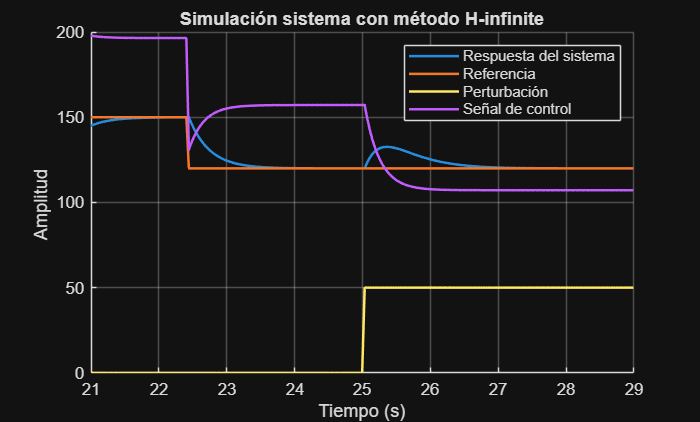

lambdah = 0.9*T;
h= 0; % porque no hay tiempo muerto


Kch = (1/Kp)*(T/(lambdah+h))*((h+2*lambdah-(lambdah^2/T))/(h+lambdah));
Tih = (T*(h+2*lambdah)-lambdah^2)/(T + h);

C3 = Kch *(1 + 1/(Tih*s));

Myr2 = ( C3 * P ) /(1+ C3 * P ) ;
Myd2 = minreal ( P /(1+ C3 * P ) ) ;
Mur2 = C2/(1+C2*P);
Mud2 = (-C2*P)/(1+C2*P);

r = u_sindc;
d = 0; %perturbacion
d (t1 >= 25) = 50;
yr2 = lsim ( Myr2 , r , t1 ) ;
yd2 = lsim ( Myd2 , d , t1 ) ;
y2 = yr2 + yd2;

yr3= lsim(Myr2, r2, t1);
y3 = yr3 + yd2;
ur2 = lsim (Mur2, r2, t1);
ud2 = lsim(Mud2, d, t1);
u2 = ur2 + ud2;


figure (15);
title ('Simulación sistema con método H-infinite') ;
xlabel ('Tiempo (s)') ;
ylabel ('Amplitud ') ;
hold on ;
grid ('on') ;
plot (t1 , y3,t1,r2,t1,d,t1,u2, 'LineWidth', 1.5);
hold on;
legend('Respuesta del sistema', 'Referencia', 'Perturbación','Señal de control');
xlim ([21 29])

## Índices para resultados teóricos H-infinite

% Error
indices = t1 >= 24;   % Índices de los valores de tiempo mayores o iguales a 24
indices_r = t1 <= 24.5; % índices para los valores de tiempo menores o iguales a 24.5 para servocontrol
indices_te = t1 >= 25;
r_after_24 = r(indices);   % Valores de 'r' después de t=24
y2_after_24 = y2(indices); % Valores de 'y2' después de t=24
r_before_24 = r(indices_r);
y2_before_24 = y2(indices_r);
t1_te = t1(indices_te);
r_te = r(indices_te);
y3_te = y3(indices_te);

% Calcular el error H-infinito 
e_HinfT = r_after_24 - y2_after_24;
e_HinfT_r = r_before_24 - y2_before_24;

% Valor final de la referencia (estado estacionario)
y_final = r2(end);

% Calcular los límites del 2% (±2%)
y98 = 0.98 * y_final; % 98% del valor final
y102 = 1.02 * y_final; % 102% del valor final

% Encontrar índices donde la respuesta está dentro de la banda ±2%
ind_98 = find((y3_te >= y98), 2, 'first');
ind_98 = ind_98(2); % Tomar el segundo elemento

% Encontrar índices donde la respuesta está dentro de la banda ±2%
ind_102 = find((y3_te <= y102), 2, 'first');
ind_102 = ind_102(2); % Tomar el segundo elemento

% Tomar el máximo de ambos índices
ind_te2 = max(ind_98, ind_102);

% Calcular te2 restando el punto de perturbación
te2_hinfT = t1_te(ind_te2) - 25;

% Cálculo de índices de desempeño
IAEd_HinfT = sum(abs(e_HinfT)) * Ts;
IAEr_HinfT = sum(abs(e_HinfT_r)) * Ts;
ISEd_HinfT = sum(e_HinfT.^2) * Ts;
EmaxhinfT= max(abs(e_HinfT)); % Error máximo
TVud_hinfT = sum(abs(diff(u2))); % esfuerzo de control

IAEd_HinfT

IAEd_HinfT =        11.304


IAEr_HinfT

IAEr_HinfT =        9.4283


ISEd_HinfT

ISEd_HinfT =          96.9


EmaxhinfT

EmaxhinfT =        12.637


TVud_hinfT

TVud_hinfT =        272.68


te2_hinfT

te2_hinfT =         1.401


# Gráfica experimental con el controlador H-infinite

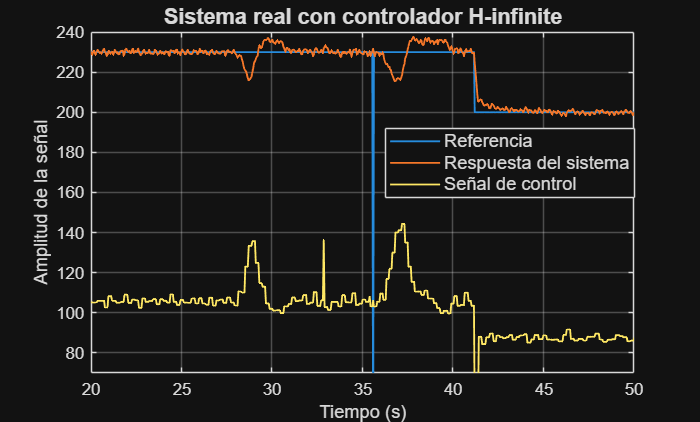

datah = readmatrix("../Data/datos_hinfinite.csv");
th = datah(:,1); %tiempo
rh = datah(:,2); %señal de referencia
uh = datah(:,3); %señal de control
yh = datah(:,4);

figure(16);
plot(th,rh,th,yh,th,uh,'LineWidth',1.1);
xlabel('Tiempo (s)','FontSize',11);
ylabel('Amplitud de la señal','FontSize',11);
legend('Referencia','Respuesta del sistema','Señal de control','FontSize',11, "Position", [0.5506 0.5508 0.3571, 0.1262]);
title('Sistema real con controlador H-infinite', 'FontSize',13);
ylim ([70 240])
xlim ([20 50])
grid on;

## Cálculo de índices para el controlador H-inifinito

% Error servo
t5 = 37.4544;
t6 = 51.1901;
idx2 = (th >= t5) & (th <= t6);
Tshinf = mean(diff(th(idx2)));  % El tiempo de muestreo 
e_hinfinite = rh(idx2) - yh(idx2);

% Error regulatorio
t14 = 28.35;
t15 = 34;
idx2d = (th >= t14) & (th <= t15);
ed_hinfinite = rh(idx2d) - yh(idx2d);

% Cálculo de índices de desempeño servocontrol
IAEr_hinf = sum(abs(e_hinfinite)) * Tshinf;
ISEr_hinf = sum(e_hinfinite.^2) * Tshinf;
% Cálculo de índices de desempeño regulatorio
IAEd_hinf = sum(abs(ed_hinfinite)) * Tshinf;
ISEd_hinf = sum(ed_hinfinite.^2) * Tshinf;
emaxd_hinf = max(abs(ed_hinfinite));           
TVud_hinf  = sum(abs(diff(uh(idx2d))));  

yfinalhinf = 260; %Arreglar esto, poner el inicio y ya
bandahinf = yfinalhinf * 0.02;
ind_hinf = find((abs(ed_hinfinite) <= bandahinf), 13, 'first');
ind_te2_hinf = max(ind_hinf);
te2_hinf = ind_te2_hinf * Tshinf;

te2_hinf

te2_hinf =        1.5313




IAEd_hinf

IAEd_hinf =        16.715


ISEd_hinf

ISEd_hinf =        111.84


IAEr_hinf

IAEr_hinf =        28.208


ISEr_hinf

ISEr_hinf =        161.05


emaxd_hinf

emaxd_hinf =         14.22


TVud_hinf

TVud_hinf =        171.35


# Cálculo del controlador discreto

%sisotool(Hz)
load ('Controlador_discreto.mat')
sisotool ('Controlador_discreto.mat')